# **Composite Functions**

Este es un nuevo operador que se introduce para ahorrar tiempo al escribir formulas como todos los demas. Su definición es simple y su función tambien, no es mas que una función dentro de otra:


$$\left(f\circ g\right)\left(x\right)=f\;\left(g\left(x\right)\right)$$


Siendo aun mas practico si no lo captas, supon que tenemos 2 funciones:


$$\begin{array}{l}
g\left(x\right)=x+1\\
f\left(x\right)=\sqrt{x}\\
g\left(a\right)=a+1\;\mathrm{obviamente}\\
f\left(a+1\right)=f\left(g\left(a\right)\right)=\left(f\circ g\right)\left(x\right)=\sqrt{a+1}
\end{array}$$


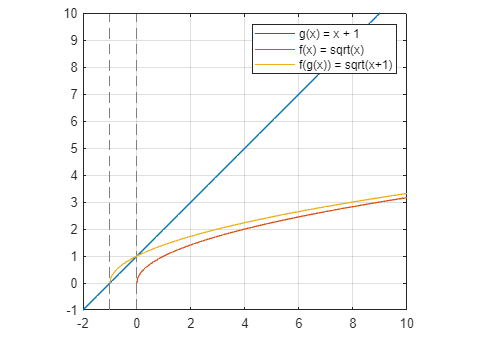

% Declaramos variable simbólica
syms x

% Definimos funciones
g(x) = x + 1;
f(x) = sqrt(x);

% Composición de funciones
fog(x) = f(g(x));   % sqrt(x+1)

% Dibujamos
figure('Position',[100 100 500 350])

tiledlayout(1,1,'Padding','compact','TileSpacing','compact')
nexttile

fplot(g(x), [-2 10])
hold on
fplot(f(x), [-2 10])      % dominio válido de sqrt(x)
fplot(fog(x), [-2 10])  % dominio válido de sqrt(x+1)
hold off

legend('g(x) = x + 1', 'f(x) = sqrt(x)', 'f(g(x)) = sqrt(x+1)')
grid on
axis equal

xlim([-2 10])
ylim([-1 10])

Es muy obvio que la funcion (f o g)(x) es diferente que las funciones por las que esta compuesta, pero lo que cabe resaltar es que (f o g)(x) es diferente de (g o f)(x), algunos pensaran que es obvio, y lo es la verdad, porque no tienen porque seguir la propiedad conmutativa de los numeros del algebra, y ademas porque si cambias de posición las funciones obviamente el resultado sera diferente.